# SPECTER Planar Dynamics Model

clear
clc
close all

## Initial Conditions

x0 = 0;
z0 = 0;
vx0 = 0;
vz0 = 0;
theta0 = deg2rad(2);
omega0 = 0;
delta0 = 0;

X0 = [x0;
    z0;
    vx0;
    vz0;
    theta0;
    omega0;
    delta0];

## Parameters

% Vehicle Specific
p.l = 0.3;
p.I = 0.5;

% TVC Command
p.gimbalTime = [0 0.5 0.55 0.60 2.0];
p.gimbalData = deg2rad([0 0 0.5 0 0]);

% Mass
p.mWet = 10;
p.mDry = 9;

% Atmosphere 
p.T0 = 288.15; 
p.P0 = 101325;
p.L = 0.0065;
p.R = 287.05;
p.gammaAir = 1.4;
p.g = 9.80665;

% Aerodynamics
p.Cd = 0.5;
p.Aref = 0.01;
p.CNa = 2.0;

% Stability
p.dCP = 0.15;

% Thrust
p.thrustTime = [0 0.1 0.3 1.0 1.8 2.0];
p.thrustData = [0 150 220 210 180 0];
p.tb = p.thrustTime(end);

% Gimbal/Servo
p.deltaMax = deg2rad(5);  
p.deltaRateMax = deg2rad(60);  
p.tauServo = 0.05;

## Attitude Controller

p.thetaCmd = deg2rad(0);

p.Kp = 2.0;
p.Kd = 0.75;

## Liftoff Calculation

liftoffBalance = @(t) ...
    ThrustModelPlanar(t,p) - MassModelPlanar(t,p)*p.g;

tLiftoff = fzero(liftoffBalance,[0 0.1]);

T_liftoff = ThrustModelPlanar(tLiftoff,p);
m_liftoff = MassModelPlanar(tLiftoff,p);
W_liftoff = m_liftoff*p.g;

fprintf('\n--- LIFTOFF CHECK ---\n\n');


--- LIFTOFF CHECK ---



fprintf('Liftoff time: %.6f s\n',tLiftoff);

Liftoff time: 0.065165 s


fprintf('Thrust at liftoff: %.6f N\n',T_liftoff);

Thrust at liftoff: 97.746977 N


fprintf('Weight at liftoff: %.6f N\n',W_liftoff);

Weight at liftoff: 97.746977 N


fprintf('T - W at liftoff: %.12e N\n',T_liftoff - W_liftoff);

T - W at liftoff: -1.421085471520e-14 N


## Simulation

tfinal = 2;

dynamics = @(t,X) SpecterDynamicsPlanar(t,X,p);

solverOptions = odeset( ...
    'RelTol',1e-6, ...
    'AbsTol',1e-8);

tic

[t,X] = ode45(dynamics,[tLiftoff,tfinal],X0,solverOptions);

toc

Elapsed time is 0.037270 seconds.


## State Histories

x = X(:,1);
z = X(:,2);
vx = X(:,3);
vz = X(:,4);
theta = X(:,5);
omega = X(:,6);
delta = X(:,7);

Vstate = sqrt(vx.^2 + vz.^2);

gamma = zeros(size(t));
alphaAOA = zeros(size(t));

VminAOA = 1.0;   

validAero = Vstate >= VminAOA;

gamma(validAero) = atan2( ...
    vx(validAero), ...
    vz(validAero));

alphaAOA(validAero) = ...
    theta(validAero) - gamma(validAero);

## TVC and Actuator Histories

deltaCmdHist = zeros(size(t));
MaeroHist = zeros(size(t));
MtvcHist = zeros(size(t));

for i = 1:length(t)

    deltaCmdHist(i) = ...
    AttitudeControllerPlanar(theta(i),omega(i),p);

    [Nx_i,Nz_i,~,~,~] = NormalForceModelPlanar( ...
        z(i),vx(i),vz(i),theta(i),p);

    MaeroHist(i) = AeroMomentModelPlanar( ...
        theta(i),Nx_i,Nz_i,p);

    T_i = ThrustModelPlanar(t(i),p);

    MtvcHist(i) = p.l*T_i*sin(delta(i));

end

## Mass History

mass = zeros(size(t));

for i = 1:length(t)
    mass(i) = MassModelPlanar(t(i),p);
end

## Aerodynamic History

V = zeros(size(t));
D = zeros(size(t));
Dx = zeros(size(t));
Dz = zeros(size(t));
rho = zeros(size(t));
a = zeros(size(t));
Mach = zeros(size(t));

for i = 1:length(t)

    V(i) = sqrt(vx(i)^2 + vz(i)^2);

    [~,~,rho(i),a(i)] = AtmosphereModelPlanar(z(i),p);
    
    Mach(i) = V(i)/a(i);

    [Dx(i),Dz(i),D(i)] = DragModelPlanar(z(i),vx(i),vz(i),p);

end

## Flight Metrics

[maxMach,idxMach] = max(Mach);

maxAlpha = max(abs(rad2deg(alphaAOA)));

minVz = min(vz);
minZ = min(z);

fprintf('\n--- FLIGHT METRICS ---\n\n');


--- FLIGHT METRICS ---




fprintf('Maximum Mach: %.6f\n',maxMach);

Maximum Mach: 0.058497


fprintf('Altitude at maximum Mach: %.6f m\n',z(idxMach));

Altitude at maximum Mach: 18.619110 m


fprintf('Minimum atmospheric density: %.6f kg/m^3\n',min(rho));

Minimum atmospheric density: 1.222593 kg/m^3



fprintf('Maximum |angle of attack|: %.6f deg\n',maxAlpha);

Maximum |angle of attack|: 2.526333 deg



fprintf('Minimum vertical velocity: %.6f m/s\n',minVz);

Minimum vertical velocity: 0.000000 m/s


fprintf('Minimum altitude: %.6f m\n',minZ);

Minimum altitude: 0.000000 m


## Drag Direction Verification

dragPower = Dx.*vx + Dz.*vz;
maxDragPower = max(dragPower);

fprintf('\n--- DRAG DIRECTION VERIFICATION ---\n\n');


--- DRAG DIRECTION VERIFICATION ---



fprintf('Maximum D dot V: %.12e W\n',maxDragPower);

Maximum D dot V: 0.000000000000e+00 W


## Final State Summary

fprintf('\n--- PLANAR MODEL FINAL STATE ---\n\n');


--- PLANAR MODEL FINAL STATE ---




fprintf('Final horizontal position: %.6f m\n',x(end));

Final horizontal position: 0.394847 m


fprintf('Final altitude: %.6f m\n',z(end));

Final altitude: 20.586143 m



fprintf('Final horizontal velocity: %.6f m/s\n',vx(end));

Final horizontal velocity: 0.252179 m/s


fprintf('Final vertical velocity: %.6f m/s\n',vz(end));

Final vertical velocity: 19.404736 m/s



fprintf('Final pitch angle: %.6f deg\n', ...
    rad2deg(theta(end)));

Final pitch angle: 0.017838 deg



fprintf('Final pitch rate: %.6f deg/s\n', ...
    rad2deg(omega(end)));

Final pitch rate: 0.029090 deg/s



fprintf('Final gimbal angle: %.6f deg\n', ...
    rad2deg(delta(end)));

Final gimbal angle: -0.035999 deg


## Actuator Verification

deltaRateNumerical = gradient(delta,t);

fprintf('\n--- ACTUATOR VERIFICATION ---\n\n');


--- ACTUATOR VERIFICATION ---




fprintf('Maximum commanded gimbal angle: %.6f deg\n', ...
    max(abs(rad2deg(deltaCmdHist))));

Maximum commanded gimbal angle: 4.000000 deg



fprintf('Maximum actual gimbal angle: %.6f deg\n', ...
    max(abs(rad2deg(delta))));

Maximum actual gimbal angle: 1.564757 deg



fprintf('Maximum actual gimbal rate: %.6f deg/s\n', ...
    max(abs(rad2deg(deltaRateNumerical))));

Maximum actual gimbal rate: 60.000000 deg/s



fprintf('Specified gimbal rate limit: %.6f deg/s\n', ...
    rad2deg(p.deltaRateMax));

Specified gimbal rate limit: 60.000000 deg/s


## TVC and Aerodynamic Response Summary

fprintf('\n--- TVC / AERODYNAMIC RESPONSE ---\n\n');


--- TVC / AERODYNAMIC RESPONSE ---




fprintf('Maximum |attitude|: %.6f deg\n', ...
    max(abs(rad2deg(theta))));

Maximum |attitude|: 2.000000 deg



fprintf('Maximum |AoA|: %.6f deg\n', ...
    max(abs(rad2deg(alphaAOA))));

Maximum |AoA|: 2.526333 deg



fprintf('Maximum |TVC moment|: %.6f N*m\n', ...
    max(abs(MtvcHist)));

Maximum |TVC moment|: 1.243020 N*m



fprintf('Maximum |aerodynamic moment|: %.6f N*m\n', ...
    max(abs(MaeroHist)));

Maximum |aerodynamic moment|: 0.009007 N*m



fprintf('Final pitch rate: %.6f rad/s\n',omega(end));

Final pitch rate: 0.000508 rad/s


## Controller Performance

attitudeError = p.thetaCmd - theta;

fprintf('\n--- CONTROLLER PERFORMANCE ---\n\n');


--- CONTROLLER PERFORMANCE ---




fprintf('Initial attitude: %.6f deg\n', ...
    rad2deg(theta(1)));

Initial attitude: 2.000000 deg



fprintf('Final attitude: %.6f deg\n', ...
    rad2deg(theta(end)));

Final attitude: 0.017838 deg



fprintf('Maximum |attitude error|: %.6f deg\n', ...
    max(abs(rad2deg(attitudeError))));

Maximum |attitude error|: 2.000000 deg



fprintf('Maximum |pitch rate|: %.6f deg/s\n', ...
    max(abs(rad2deg(omega))));

Maximum |pitch rate|: 7.370253 deg/s



fprintf('Maximum |commanded gimbal|: %.6f deg\n', ...
    max(abs(rad2deg(deltaCmdHist))));

Maximum |commanded gimbal|: 4.000000 deg



fprintf('Maximum |actual gimbal|: %.6f deg\n', ...
    max(abs(rad2deg(delta))));

Maximum |actual gimbal|: 1.564757 deg


## Controller Response Metrics

thetaDeg = rad2deg(theta);
thetaCmdDeg = rad2deg(p.thetaCmd);

% Overshoot past the commanded attitude
undershoot = min(thetaDeg - thetaCmdDeg);

fprintf('\n--- CONTROLLER RESPONSE METRICS ---\n\n');


--- CONTROLLER RESPONSE METRICS ---




fprintf('Minimum attitude relative to command: %.6f deg\n', ...
    undershoot);

Minimum attitude relative to command: 0.017317 deg



% 2-percent-style absolute settling band based on initial error
initialErrorDeg = abs(thetaDeg(1) - thetaCmdDeg);
settlingBand = 0.02*initialErrorDeg;

settlingTime = NaN;

for i = 1:length(t)

    remainingError = abs(thetaDeg(i:end) - thetaCmdDeg);

    if all(remainingError <= settlingBand)
        settlingTime = t(i);
        break
    end

end

fprintf('Settling band: +/- %.6f deg\n',settlingBand);

Settling band: +/- 0.040000 deg



if isnan(settlingTime)
    fprintf('Settling time: Not settled within simulation window\n');
else
    fprintf('Settling time: %.6f s\n',settlingTime);
end

Settling time: 1.537878 s


## Plots

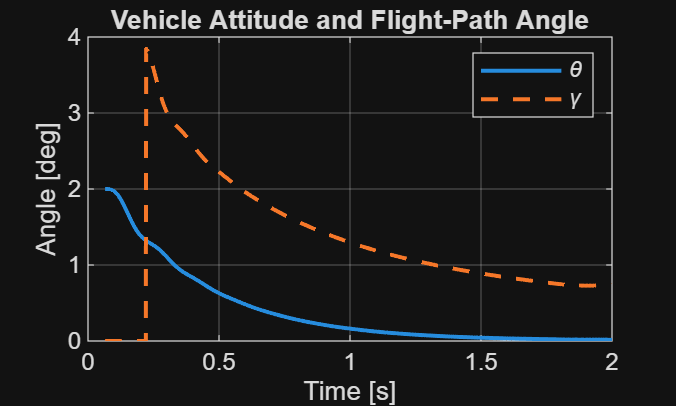

% Attitude vs trajectory
figure
plot(t,rad2deg(theta),'LineWidth',1.5)
hold on
plot(t,rad2deg(gamma),'--','LineWidth',1.5)
xlabel('Time [s]')
ylabel('Angle [deg]')
legend('\theta','\gamma')
title('Vehicle Attitude and Flight-Path Angle')
grid on

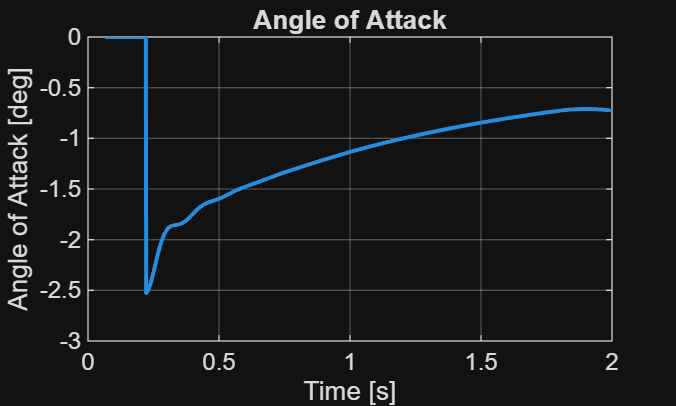


% Angle of attack
figure
plot(t,rad2deg(alphaAOA),'LineWidth',1.5)
xlabel('Time [s]')
ylabel('Angle of Attack [deg]')
title('Angle of Attack')
grid on

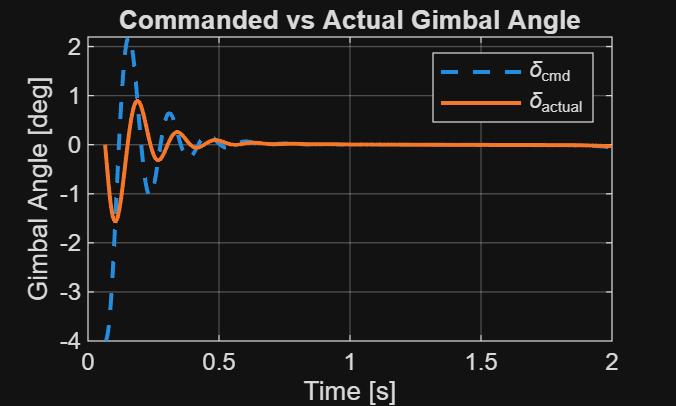


% Commanded vs actual gimbal
figure
plot(t,rad2deg(deltaCmdHist),'--','LineWidth',1.5)
hold on
plot(t,rad2deg(delta),'LineWidth',1.5)
xlabel('Time [s]')
ylabel('Gimbal Angle [deg]')
legend('\delta_{cmd}','\delta_{actual}')
title('Commanded vs Actual Gimbal Angle')
grid on

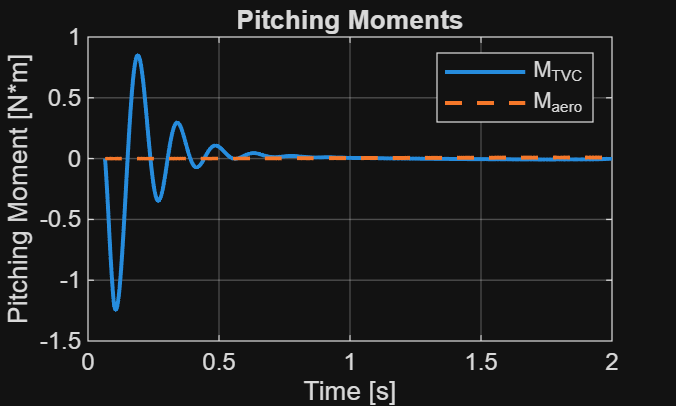


% Pitching moments
figure
plot(t,MtvcHist,'LineWidth',1.5)
hold on
plot(t,MaeroHist,'--','LineWidth',1.5)
xlabel('Time [s]')
ylabel('Pitching Moment [N*m]')
legend('M_{TVC}','M_{aero}')
title('Pitching Moments')
grid on

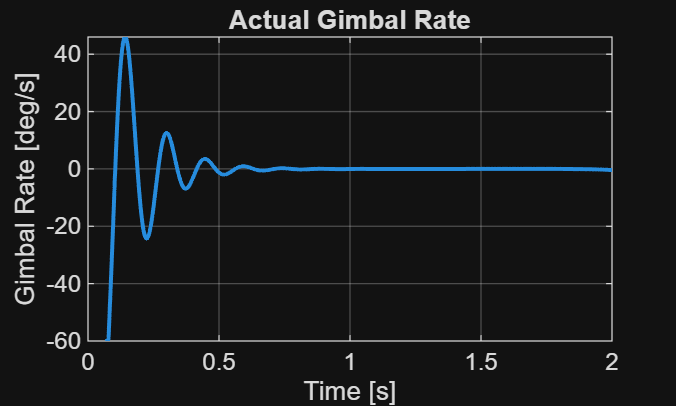


% Gimbal rate
figure
plot(t,rad2deg(deltaRateNumerical),'LineWidth',1.5)
xlabel('Time [s]')
ylabel('Gimbal Rate [deg/s]')
title('Actual Gimbal Rate')
grid on